%% Code for Discrete Convolution
clc
clear
pause on
filename = 'Enter your folder path /test.gif';
x=[0 2 2 2 0];          %f signal
h=[0 1 2 2 0];          %g signal
m=length(x);
n=length(h);
%invierte el vector h
hi=fliplr(h);
length=4*(m+n);
k=length/2;

X=[x,zeros(1,length-m)]

X =      0     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


X= X([ end-k+1:end 1:end-k ])

X =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     2     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


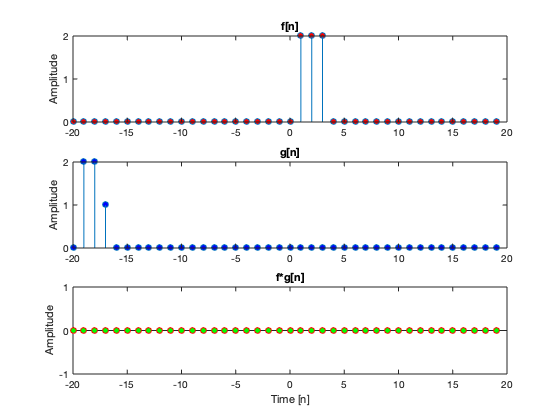

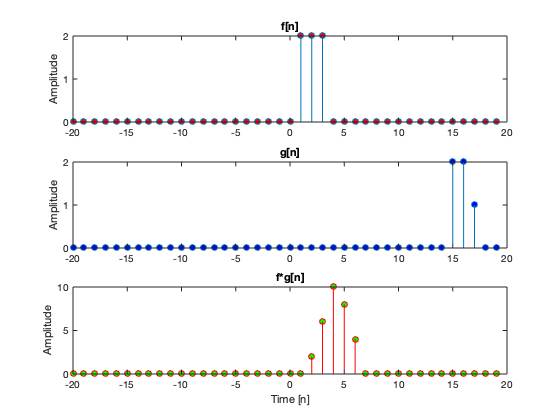

H=[h,zeros(1,length-n)];
H= H([ end-k+1:end 1:end-k ]);

xn=-length/2:length/2-1;
Y=zeros(1,length);
p=zeros(1,length);

figure(1)
set(gcf,'color','w');
h1=subplot(3,1,1);
stem(xn,X,'MarkerFaceColor','red')
ylabel('Amplitude')
title('f[n]')
% set(h1,'YLim',[a b])
h2=subplot(3,1,2);
stem(xn,H,'MarkerFaceColor','blue')
% set(h2,'YLim',[a b])
pause(3)
h2=subplot(3,1,3);
stem(xn,Y,'MarkerFaceColor','green')
%
Hi=[hi,zeros(1,length-n)];
for i=1:length-n
    p=X.*Hi;
    Y(i+n-1)=sum(p);
    subplot(3,1,2);
    stem(xn,Hi,'MarkerFaceColor','blue')
    ylabel('Amplitude')
    title('g[n]')
    subplot(3,1,3)
    stem(xn,Y,'r','MarkerFaceColor','green')
    xlabel('Time [n]')
    ylabel('Amplitude')
    title('f*g[n]')
    Hi= Hi([ end 1:end-1 ]);
    pause(0.07)
    drawnow
    frame = getframe(1);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    if i == 1;
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append');
    end
end

pause off
salida=Y(abs(Y)>0);
imfinfo(filename)

ans = 1×35 struct array with fields:
    Filename
    FileModDate
    FileSize
    Format
    FormatVersion
    Left
    Top
    Width
    Height
    BitDepth
    ColorType
    FormatSignature
    BackgroundColor
    AspectRatio
    ColorTable
    Interlaced
    DelayTime
    DisposalMethod
